# read images

Read the target image containing a cluttered scene.

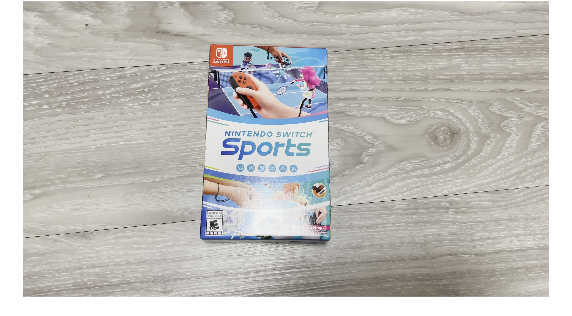

vidReader = VideoReader('./IMG_5905.MOV','CurrentTime',1);
template = read(vidReader, 150);
templateImg = rgb2gray(template); % in some versions, using im2grpy(frameRGB)
figure;
imshow(template);
title('Template image');

## Generate a patch from the reference image

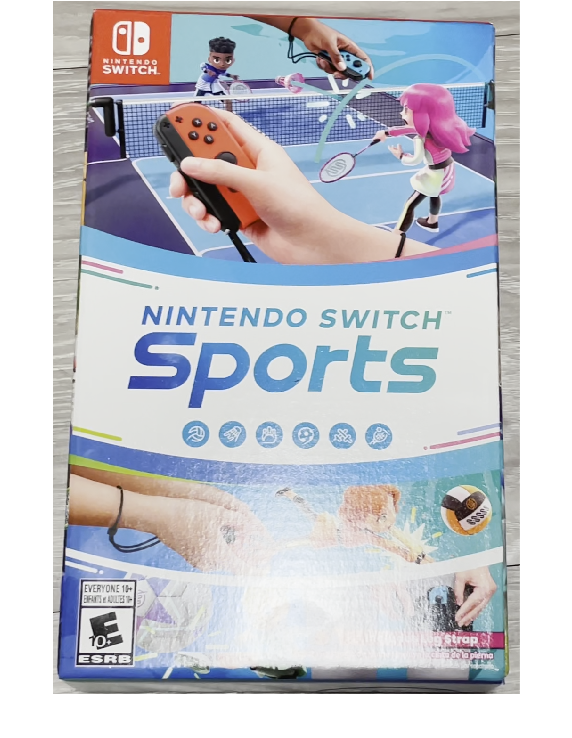

x = 1285; y = 300; offsetX = 990; offsetY = 1470;
templateP = imcrop(template, [x y offsetX offsetY]);
templatePatch = imcrop(templateImg, [x y offsetX offsetY]);
figure
imshow(templateP);
title('Template patch');

## Randomly select another frame

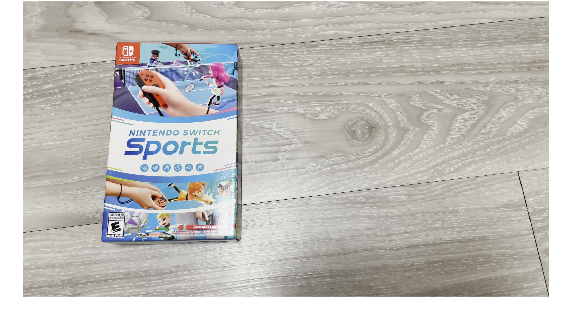

randImg = read(vidReader, 15);
randImage = rgb2gray(randImg); % in some versions, using im2grpy(frameRGB)
figure
imshow(randImg);
title('A random frame');

## Calculate the normalized correlation matrix

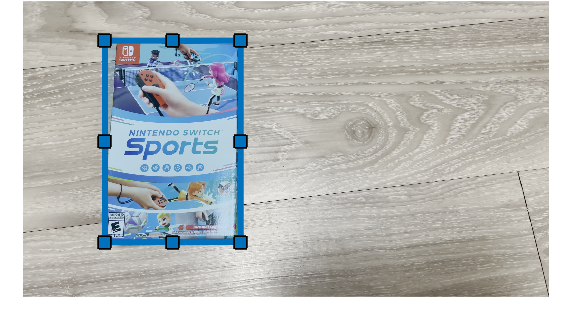

c = normxcorr2(templatePatch, randImage);
[ypeak, xpeak] = find(c==max(c(:)));
% Compute translation from max location in correlation matrix
yoffSet = ypeak-size(templatePatch,1);
xoffSet = xpeak-size(templatePatch,2);
figure
hAx  = axes;
randImage = read(vidReader, 15);
imshow(randImage,'Parent', hAx);

drawrectangle(hAx, 'Position', [xoffSet+1, yoffSet+1, size(templatePatch,2), size(templatePatch,1)]);
title('Matching with normalized correlation');